# Mobile robot short Project

BY Marc Guitart & Caterina Moll

link: 

Given the kown workspace: Sensors_Data.mat, and  Enviroment.png

Answer the following question:

## Pose estimation given encoder data (10%)

Before start:

- Open the Simulink model EKF_Pose_estimation.slx and get familiar with: 'Where2Find_Code.pdf'. 

- Have a look to section See an animation of the file: 3_MR_SP_support.mlx 

Every thing is done, the exercise consist in compile in a mlx file all the concepts.

1.- Implement in this mlx file:

a) Pose_theoric, asumme no noise. (review **Mobile Robot Kinematics** folder)

b) Pose_estimation by adding noise in odometry. review **Pose uncertanty** folder)

c) Ricatti equation for estimating the covariance matrix representing the uncertanty in the robot pose. 

2.- Display in a figure:

a) x,y poses for both trajectories: theoric and estimated 

b) ellipses representing x,y uncertanty. Do it every 15-20 poses.

c) represent uncertanty in orientation by adding a isosceles triange in front of the robot the base 

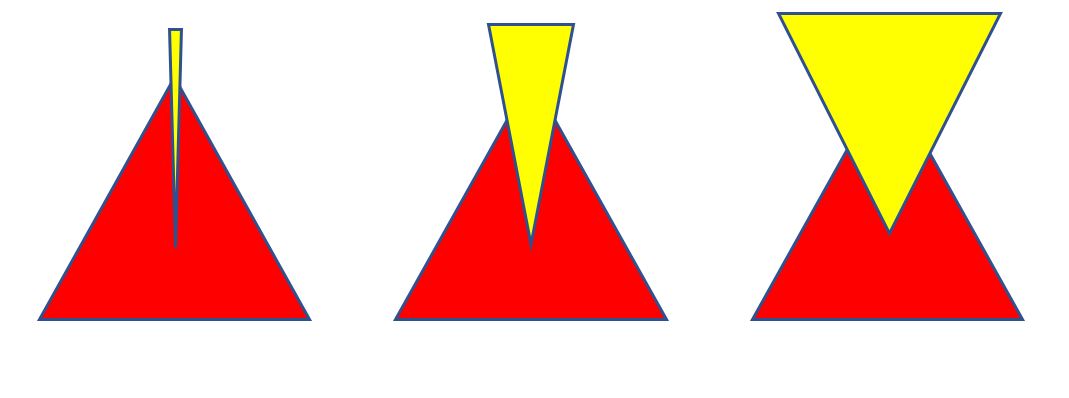

The robot will be represented by a triangle: Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]

Record a movie of the robot moving along the corridor displaying both trajectories.

 See: help VideoWriter to get familiar with the matlab functions

1- a) 

close all
clf
load("Sensors_Data.mat");
load('Encoder_Data.mat')
L_speed = left_angular_speed;  L_speed(:,2) = L_speed(:,2) .* r_w ./ 100;
R_speed = right_angular_speed; R_speed(:,2) = R_speed(:,2) .* r_w ./ 100;

L_displ = L_speed; L_displ(:,2) = L_displ(:,2) .* Ts;
R_displ = R_speed; R_displ(:,2) = R_displ(:,2) .* Ts;

S = 0.26;
delta_d  = (L_displ(:,2) + R_displ(:,2)) / 2;
delta_th = (R_displ(:,2) - L_displ(:,2)) / (2*S);

tx = 8.65; ty = 17.2; alpha = -pi/2;
Pose_theoric(:,:,1) = transl(tx,ty,0) * trotz(alpha); % initial pose
for i = 2:length(delta_th)
    Pose_theoric(:,:,i)         = Pose_theoric(:,:,i-1) * transl(delta_d(i-1),0,0) * trotz(delta_th(i-1));
    Position_theoric(:,i)       = transl(Pose_theoric(:,:,i-1));
    Orientation_theoric(:,i)    = tr2rpy(Pose_theoric(:,:,i-1));
end

b) 

ProcNoiseD      = 0.025^2; % testing with some values to have more difference between theoric and estimated. Original was 0.019^2
ProcNoiseTheta  = 0.009^2; % testing with some values to have more difference between theoric and estimated. Original was 0.003^2

V = ...
    [   ProcNoiseD  0;              ...
        0           ProcNoiseTheta];

noiseD = rand*V(1,1);
noiseTheta = rand*V(2,2);

Position_estimation(:,1) = zeros(size(Position_theoric(:,1)));
Position_estimation(:,2) = Position_theoric(:,2);

Orientation_estimation = zeros(3004,1);
Orientation_estimation(2) = Orientation_theoric(3,2);

for i=3:length(delta_th)
    Position_estimation(1,i) = Position_estimation(1,i-1) + (delta_d(i)+noiseD)*cos(Orientation_estimation(i-1));
    Position_estimation(2,i) = Position_estimation(2,i-1) + (delta_d(i)+noiseD)*sin(Orientation_estimation(i-1));
    Orientation_estimation(i) = mod(Orientation_estimation(i-1) + delta_th(i) + noiseTheta , 2*pi);
end

c)

F_x = zeros([3,3,3004]);
F_x(1,1,:) = 1; F_x(2,2,:) = 1; F_x(3,3,:) = 1;
F_x(1,3,:) = -delta_d .* sin(Orientation_theoric(3,:))';
F_x(2,3,:) =  delta_d .* cos(Orientation_theoric(3,:))';

F_v = zeros([3 2 3004]);
F_v(3,2,:) = 1;
F_v(1,1,:) = cos(Orientation_theoric(3,:))';
F_v(2,1,:) = sin(Orientation_theoric(3,:))';

Pk1 = zeros([3 3 3004]);
Pk1(:,:,1) = eye(3) * 0.0001;

for i=2:3004
    Pk1(:,:,i) = F_x(:,:,i)*Pk1(:,:,i-1)*F_x(:,:,i)' + F_v(:,:,i)*[V(1) 0;0 V(2)]*F_v(:,:,i)';
end

2- a) 

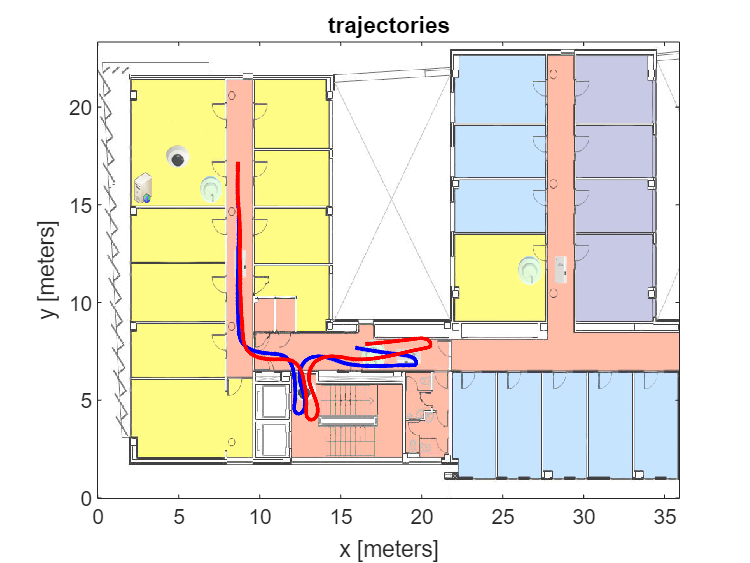

I=imread('Enviroment.png');
x_ima=[0 35.9];
y_ima=[23.31 0];
image(I,'XData',x_ima,'YData',y_ima,"AlphaData",0.75);
axis xy
hold on
    plot( ...
        Position_theoric(1,2:end), ...
        Position_theoric(2,2:end), ...
        'k', ...
        'Color','b', ...
        "LineWidth",2 ...
    )
    title('trajectories'); xlabel ('x [meters]'); ylabel ('y [meters]')
    plot( ...
        Position_estimation(1,2:end), ...
        Position_estimation(2,2:end), ...
        'k', ...
        'Color','r', ...
        "LineWidth",2 ...
    )
hold off

b)

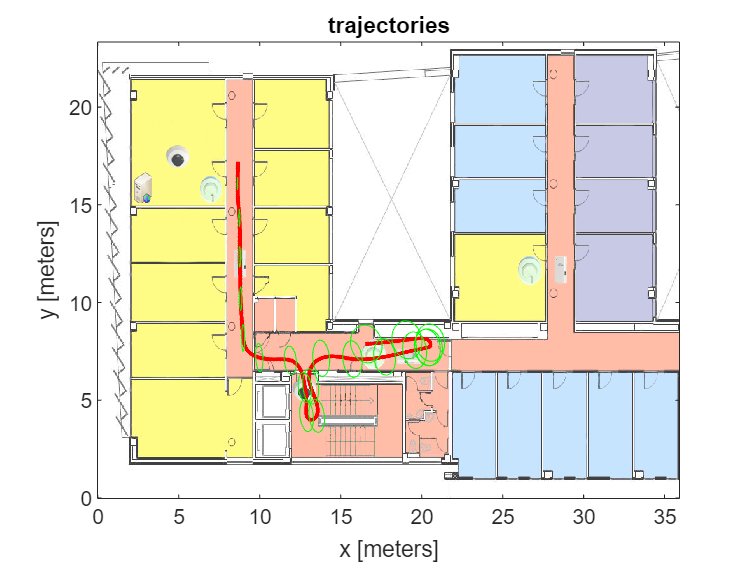

image(I,'XData',x_ima,'YData',y_ima,"AlphaData",0.75);
axis xy
hold on
    plot( ...
        Position_estimation(1,2:end), ...
        Position_estimation(2,2:end), ...
        'k', ...
        'Color','r', ...
        "LineWidth",2 ...
    )
    title('trajectories'); xlabel ('x [meters]'); ylabel ('y [meters]')
    for i=1:length(delta_th)
        if (mod(i,150)==0)
            plot_ellipse( ...
                Pk1(1:2,1:2,i), ...
                [Position_estimation(1,i), Position_estimation(2,i)], ...
                'g'...
            );
        end
    end
hold off

c)

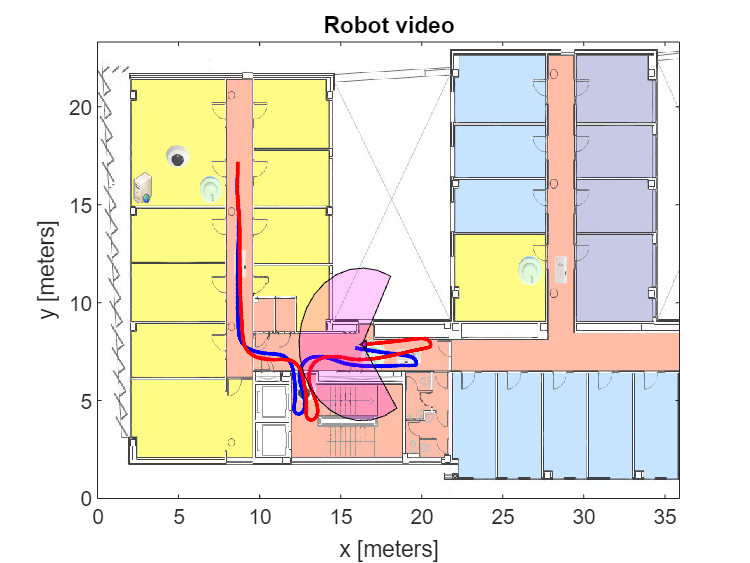

Robot= [ ...
      0 -0.2 0 1; ...
    0.4    0 0 1; ...
      0  0.2 0 1 ...
]';
Laser_Range=3.9; % meters
w=linspace(-30*pi/180,210*pi/180,20); %Laser foot print
s_x=Laser_Range*sin(w); s_y=Laser_Range*cos(w);
Lfp.v=[[s_x 0];[s_y 0]]';
Lfp.f= [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 1];
r_patch=[];s_patch=[];
speed = 5;

Robot_video = VideoWriter('Robot_Video.avi');
Robot_video.FrameRate = 45;
Robot_video.Quality = 100;
open(Robot_video);
image(I,'XData',x_ima,'YData',y_ima,"AlphaData",0.75);
axis xy
hold on
    plot( ...
        Position_theoric(1,2:end), ...
        Position_theoric(2,2:end), ...
        'k', ...
        'Color','b', ...
        "LineWidth",2 ...
    )
    title('Robot video'); xlabel ('x [meters]'); ylabel ('y [meters]')
    plot( ...
        Position_estimation(1,2:end), ...
        Position_estimation(2,2:end), ...
        'k', ...
        'Color','r', ...
        "LineWidth",2 ...
    )

    for i=2:length(delta_th)
        k_m=mod(i,speed);
        if k_m==0
            delete(r_patch);
            delete(s_patch);
            Robot_pose=transl(Position_estimation(1,i),Position_estimation(2,i),0)*trotz(Orientation_estimation(i));
            Robot_tr=Robot_pose*Robot; % moving the robot 
            Laser_fp=Robot_pose*transl(0.25,0,0)*[Lfp.v zeros(21,1) ones(21,1)]';
            axis([0 35.9 0 23.31]);
            r_patch = patch(Robot_tr(1,:), Robot_tr(2,:),'m');
            s_patch = patch('Faces',Lfp.f,'Vertices',Laser_fp(1:2,:)','FaceColor','m','FaceAlpha',.2);
            %pause(0.01);
            
            frame=getframe(gcf);
            writeVideo(Robot_video,frame);
        end
    end
hold off

close(Robot_video)

## Mapping (10%)

Make a movie of laser data in Robot reference frame. See the video  of ATENEA: [Movie of the Laser Data seen in Robot Reference FrameURL](https://atenea.upc.edu/mod/url/view.php?id=3257292)

Make a video of laser data in Wordl Reference frame. Use here the code of the last TODO Lab about laser data. 

Display laser data every 2.5 m and erasing the previous walls after 200ms for better understanding.

See the video: '3_mapping.mp4' for inspiration

Mapping_video = VideoWriter('MappingVideo2');

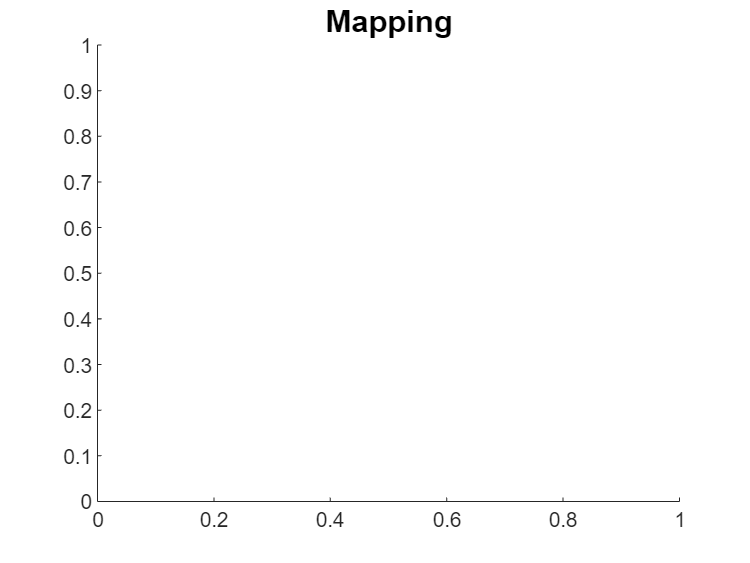

Mapping_video.FrameRate = 10;
Mapping_video.Quality = 100;
open(Mapping_video);

figure
hold on
title("Mapping", 'FontSize',15);

Ts_laser=0.4;
laser_data = log_urg(:,2:681) / 1000;

n_data_by_sampling = size(laser_data,2); 
n_sampling = size(laser_data,1);

ploted_barrier = [];

ang_res = 0.3515;
ang = [1:length(laser_data)] * ang_res-30;
ang = ang * pi/180;

[x,y] = pol2cart(ang,laser_data);
T_R_L = transl(0.6,0,0)*trotz(deg2rad(-90));

laser_points_L = [];

for landmark_i = 1:length(Log_with_correction)
    log = Log_with_correction(landmark_i);
    i = log.Time_stamp / 20;
    if i < 150
        delete(ploted_barrier);
        mapping = [];
        
        laser_points_L(1,:,i) = x(i,:);
        laser_points_L(2,:,i) = y(i,:);
        laser_points_L(3,:,i) = zeros(1,n_data_by_sampling);
        laser_points_L(4,:,i) = ones(1,n_data_by_sampling);
    
        for j = 1:length(laser_points_L(1,:,i))
            final_pose= log.Robot_pose *  T_R_L * laser_points_L(:,j,i);
            mapping = [mapping; final_pose(1) final_pose(2)];
        end
       
        ploted_barrier = scatter( ...
            mapping(:,1), ...
            mapping(:,2), ...
            1, ...
            'red', ...
            'filled' ...
        );
        
        axis ([5 30 0 20])
        
        frame=getframe(gcf);
        writeVideo(MappingVideo2,frame);
    end
end

% end
hold off

close(Mapping_video);

## Occupancy grid (30%)

Use Breshehan algorithm to build the map. Do it only when Land Marks are avalaible and the trajectory have been corrected.

Use the idea behind the line tracing: Visit: https://es.wikipedia.org/wiki/Algoritmo_de_Bresenham

See: Mapping.mlx and '4_occupancy.mp4' for inspiration

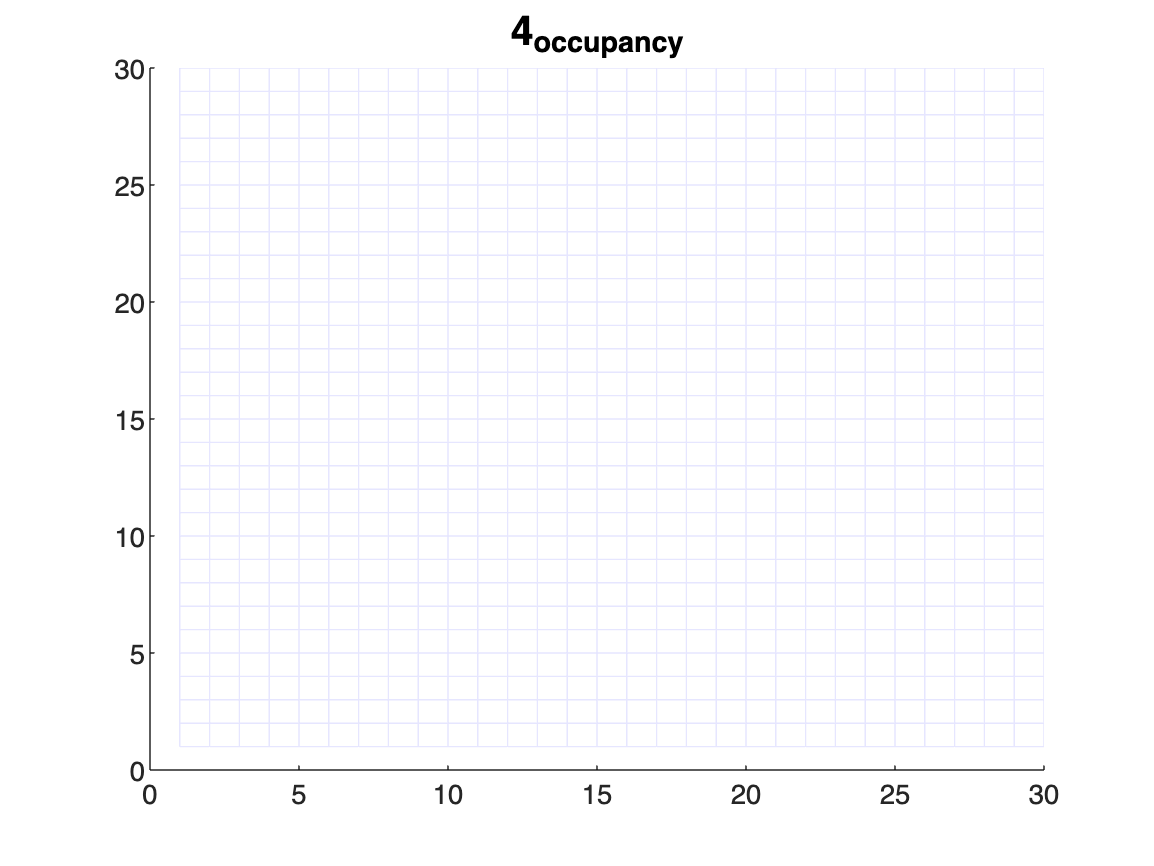

figure
hold on
title("4_occupancy", 'FontSize',15);

A = ones(100,100);
s=pcolor (A);
colormap(gray(2))
s.EdgeColor = [0.9 0.9 1];
axis ([0 30 0 30]);
drawnow;

for landmark_i = 1:length(Log_with_correction)
    log = Log_with_correction(landmark_i);
    i = log.Time_stamp / 20;
    
    if i < 150
        robot_position = transl(log.Robot_pose);
   
        for j = 1:length(laser_points_L(1,:,i))
            final_pose= log.Robot_pose *  T_R_L * laser_points_L(:,j,i);
            l_xy=bresenham([robot_position(1) robot_position(2)], final_pose(1), final_pose(2));
             
            for j = 1:length(l_xy(:,1))
                A(l_xy(j,2),l_xy(j,1))=0; % Hemos tenido que poner las x e y rotadas para que se viera bien.
            end
        end
        s = pcolor (A);
        s.EdgeColor = [0.9 0.9 1];
        colormap(gray(2));
        drawnow;
        
    end
end
hold off

## Driving the Robot (20%)

Based on what you learn in motion arquitectures use the Goint2point for driving the robot. Use 'frontend.m' function to introduce way points such to recreate a trajectory similar to the past section.

Make a video displaying both trajectories: estimated and theoric. Add the ellipses to visualize uncertanty.

Notice that in this exercise the trajectories appear as the robot moves.

load("OurPoints.mat");

Error using load
Unable to find file or directory 'waypoints.mat'.


startPose = [0,0,-pi]; % startPose [x y theta] 
goal = wp(:,2); % goal position

Kv = 0.9; % Velocity Gain. Units (m/s)/m = [1/s]
Kh = 4; % Head Gain. Units [1/s]
r = 0.1; % wheels radius
S = 0.26; % half of the distance between the wheels' center  
ts = 0.02;% sample time

currentPose = startPose;
stop = false;
figure
scatter(wp(1,46),goal);
hold on
scatter(startPose(1),startPose(2));
xlabel('x');
ylabel('y');
title('Go_To_Point')
grid
%axis([-60 60 -60 60])


## Localization (30%)

While driving the Robot in the last section Localize the Robot  by using the Similarity Transform. 

Visit again the folder 11_Localization for inspiration.

### Land Marks

Use the given Land Marks. They are known. They can be extracter from laser data, there are easy algorithms for finding they, like corner detection, etc ...

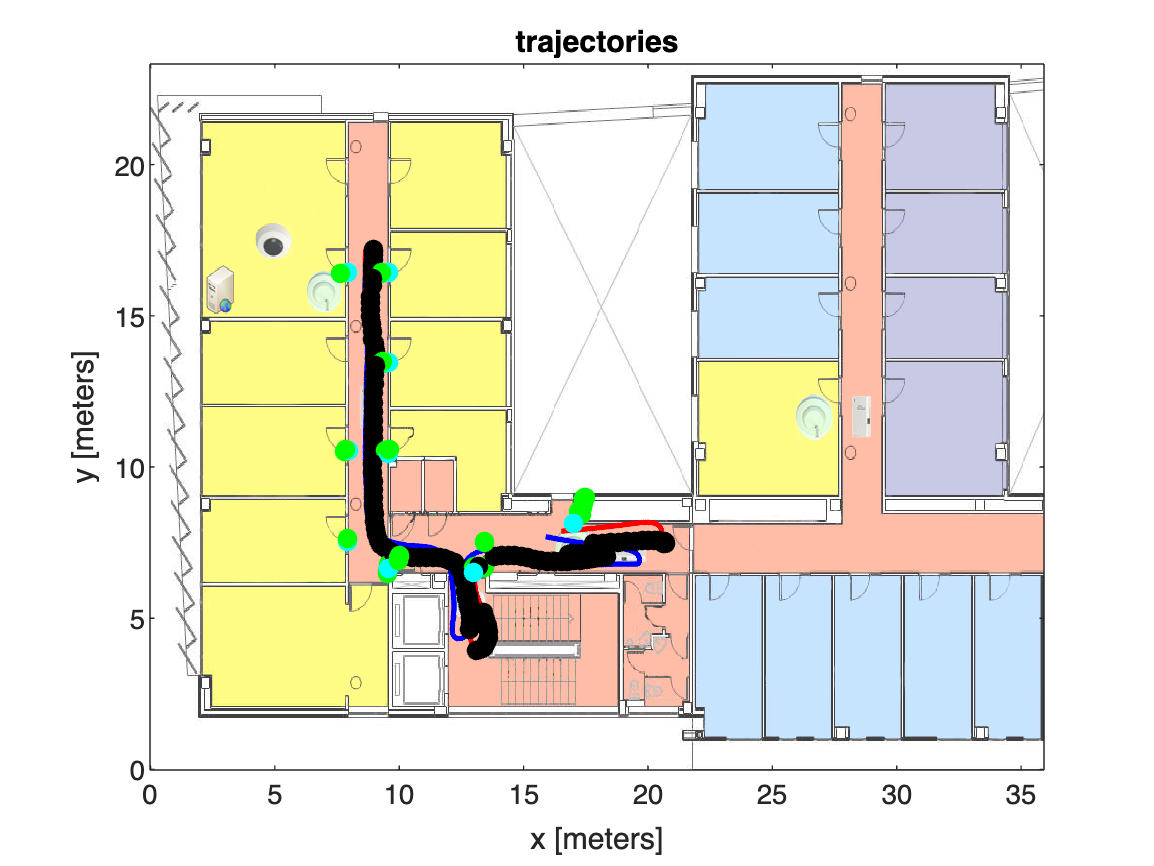

landmarks = [...
      7.934 16.431 0 1;...
      9.583 16.431 0 1;...
      9.584 13.444 0 1;...
      9.584 10.461 0 1;...
      7.973 10.534 0 1;...
      7.934  7.547 0 1;...
      9.584  6.654 0 1;...
     13.001  6.525 0 1;...
     17.007  8.136 0 1 ...
]';

Detected_landmarks = [];
Reference_landmarks = [];
Log_no_correction = [];

image(I,'XData',x_ima,'YData',y_ima,"AlphaData",0.75);
axis xy
hold on

    plot( ...
        Position_theoric(1,2:end), ...
        Position_theoric(2,2:end), ...
        'k', ...
        'Color','b', ...
        "LineWidth",2 ...
    )
    plot( ...
        Position_estimation(1,2:end), ...
        Position_estimation(2,2:end), ...
        'k', ...
        'Color','r', ...
        "LineWidth",2 ...
    )
    title('trajectories'); xlabel ('x [meters]'); ylabel ('y [meters]')
    load("l_s_d.mat")
load("l_s_b.mat")
    for time=3:length(l_s_b(:,1))
        
        Robot_pose = transl(Position_estimation(1,time),Position_estimation(2,time),0)*trotz(Orientation_estimation(time));
    
        for landmark_index=1:length(landmarks(1,:))
            if l_s_b(time,landmark_index) ~= 0
                
                d=l_s_d(time,landmark_index);
                b=l_s_b(time,landmark_index);
                
                
                [x,y]=pol2cart(b(1,1),d(1,1));
                
                L_w=Robot_pose*[x y 0 1]';
                
                Detected_landmarks  = [Detected_landmarks L_w];
                Reference_landmarks = [Reference_landmarks landmarks(1:2,landmark_index)];         
            end
        end
        
        if ~isempty(Detected_landmarks)
            
            scatter(Reference_landmarks(1,:),Reference_landmarks(2,:), 50, 'c','filled');
            scatter(Detected_landmarks(1,:),Detected_landmarks(2,:), 50, 'g','filled');   
            
            A = []; 
            for i=1:size(Reference_landmarks, 2)
                A = [A;[Reference_landmarks(1,i),Reference_landmarks(2,i),1,0]];
                A = [A;[Reference_landmarks(2,i),-Reference_landmarks(1,i),0,1]];
            end
            
            B = [];
            for i=1:size(Detected_landmarks, 2)
                B = [B; Detected_landmarks(1,i); Detected_landmarks(2,i)];
            end
            
            Similarity_transform = linsolve(A,B);
            tx_ST = Similarity_transform(3);
            ty_ST = Similarity_transform(4);
            alpha_ST = atan2(Similarity_transform(2),Similarity_transform(1));

            Error = transl(-tx_ST,-ty_ST,0)*trotz(alpha_ST);
            Corrected_robot =  Error * [transl(Robot_pose); 1];
            scatter(Corrected_robot(1),Corrected_robot(2), 50, 'black','filled');
            
            Single_log.Time_stamp = time;                                       
            Single_log.Robot_pose = Robot_pose;                                 
            Single_log.Corrected_robot = Corrected_robot;                       
            Single_log.Number_of_landmarks = length(Detected_landmarks(1,:));   
            Single_log.Error = Error;                                           
            Log_no_correction = [Log_no_correction Single_log];
        end
        
        Detected_landmarks = [];
        Reference_landmarks = [];
    end
hold off

### Correct the noisy trajectory. 

Pay attention to the relationship of the variables

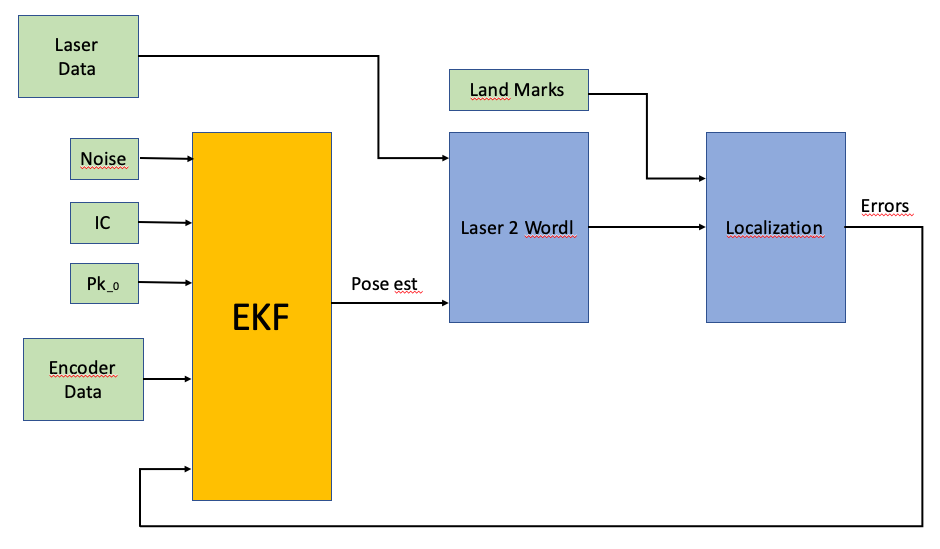

Update the estimated covarianze matrix by the sensor, knowing that the Laser scanner has and acuraccy 4 mm with a standard deviation of 0.2 mm.

1.- Display in a figure: the map, theoric trajectory (no noise) and the corrected trajectory. See: Expected_Localization.mp4

2.- Make a 'log' with the following columns:  estimated noisy pose, corrected position, number of Land-marks seen,  and the errors and the covariance matrix Pk.

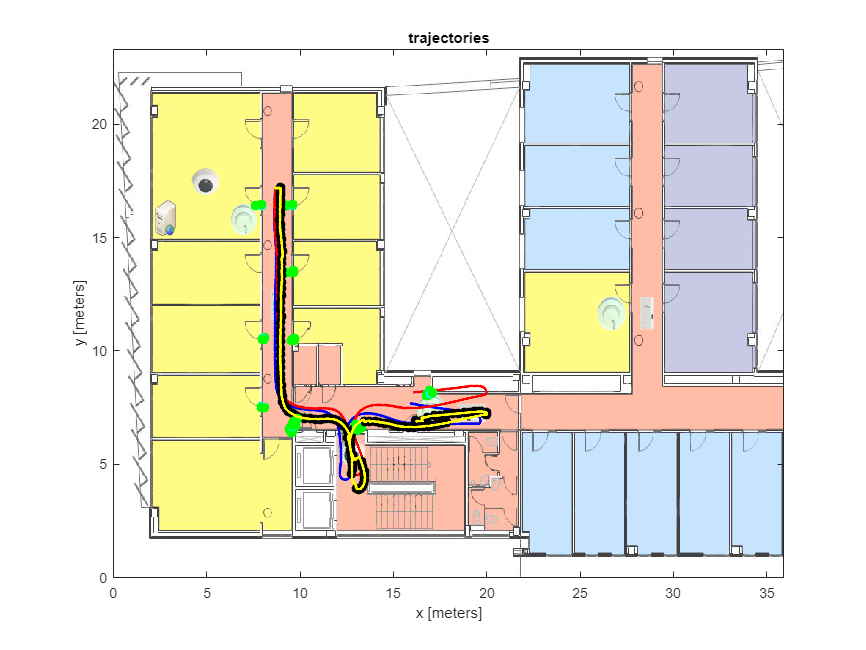

Detected_landmarks = [];
Reference_landmarks = [];
Log_with_correction = [];

Position_with_correction(:,1) = zeros(size(Position_theoric(:,1)));
Position_with_correction(:,2) = Position_theoric(:,2);

Orientation_with_correction = zeros(3004,1);
Orientation_with_correction(2) = Orientation_theoric(3,2);

Orientation_estimation;

mu_noise = 0;
mu_laser = 0;
mu_fused = 0;
    
image(I,'XData',x_ima,'YData',y_ima,"AlphaData",0.75);
axis xy
hold on

    plot( ...
        Position_theoric(1,2:end), ...
        Position_theoric(2,2:end), ...
        'k', ...
        'Color','b', ...
        "LineWidth",2 ...
    )
    plot( ...
        Position_estimation(1,2:end), ...
        Position_estimation(2,2:end), ...
        'k', ...
        'Color','r', ...
        "LineWidth",2 ...
    )
    title('trajectories'); xlabel ('x [meters]'); ylabel ('y [meters]')
    
    for time=3:length(l_s_b(:,1))
            
        Position_with_correction(1,time)  = Position_with_correction(1,time-1) + (delta_d(time)+noiseD)*cos(Orientation_with_correction(time-1));
        Position_with_correction(2,time)  = Position_with_correction(2,time-1) + (delta_d(time)+noiseD)*sin(Orientation_with_correction(time-1));
        Orientation_with_correction(time) = mod(Orientation_with_correction(time-1) + delta_th(time) + noiseTheta, 2*pi);
        
        Robot_pose = transl(Position_with_correction(1,time),Position_with_correction(2,time),0)*trotz(Orientation_with_correction(time));

        for landmark_index=1:length(landmarks(1,:))
            if l_s_b(time,landmark_index) > 0
                
                d=l_s_d(time,landmark_index);
                b=l_s_b(time,landmark_index);
                
                [x,y]=pol2cart(b(1,1),d(1,1));
                
                L_w=Robot_pose*[x y 0 1]';
                
                Detected_landmarks  = [Detected_landmarks L_w];
                Reference_landmarks = [Reference_landmarks landmarks(1:2,landmark_index)];         
            end
        end
        
        if ~isempty(Detected_landmarks)
            
            scatter(Reference_landmarks(1,:),Reference_landmarks(2,:), 50, 'c','filled');
            scatter(Detected_landmarks(1,:),Detected_landmarks(2,:), 50, 'g','filled');   
            
            A = []; 
            for i=1:size(Reference_landmarks, 2)
                A = [A;[Reference_landmarks(1,i),Reference_landmarks(2,i),1,0]];
                A = [A;[Reference_landmarks(2,i),-Reference_landmarks(1,i),0,1]];
            end
            
            B = [];
            for i=1:size(Detected_landmarks, 2)
                B = [B; Detected_landmarks(1,i); Detected_landmarks(2,i)];
            end
            
            Similarity_transform = linsolve(A,B);
            tx_ST = Similarity_transform(3);
            ty_ST = Similarity_transform(4);
            alpha_ST = atan2(Similarity_transform(2),Similarity_transform(1));
                
            Error = transl(-tx_ST,-ty_ST,0)*trotz(alpha_ST);
            Corrected_robot =  Error * [transl(Robot_pose); 1];
            scatter(Corrected_robot(1),Corrected_robot(2), 50, 'black','filled');
            Position_with_correction(1,time) = Corrected_robot(1);
            Position_with_correction(2,time) = Corrected_robot(2);
            
           
                
            Single_log.Time_stamp = time;                                       
            Single_log.Robot_pose = Robot_pose;                                 
            Single_log.Corrected_robot = Corrected_robot;                       
            Single_log.Number_of_landmarks = length(Detected_landmarks(1,:));   
            Single_log.Error = Error;                                           
            
            Log_with_correction = [Log_with_correction Single_log];
        end
            
        Detected_landmarks = [];
        Reference_landmarks = [];     
    end
    
    plot( ...
        Position_with_correction(1,2:end), ...
        Position_with_correction(2,2:end), ...
        'k', ...
        'Color','y', ...
        "LineWidth",2 ...
    )
    
hold off